addpath codes\
load data.mat

%PCM设置

opt.block_len = [800 1600];

tic
I = pcm_fcs(data,opt);

历时 85.066551 秒。


toc

历时 335.317056 秒。


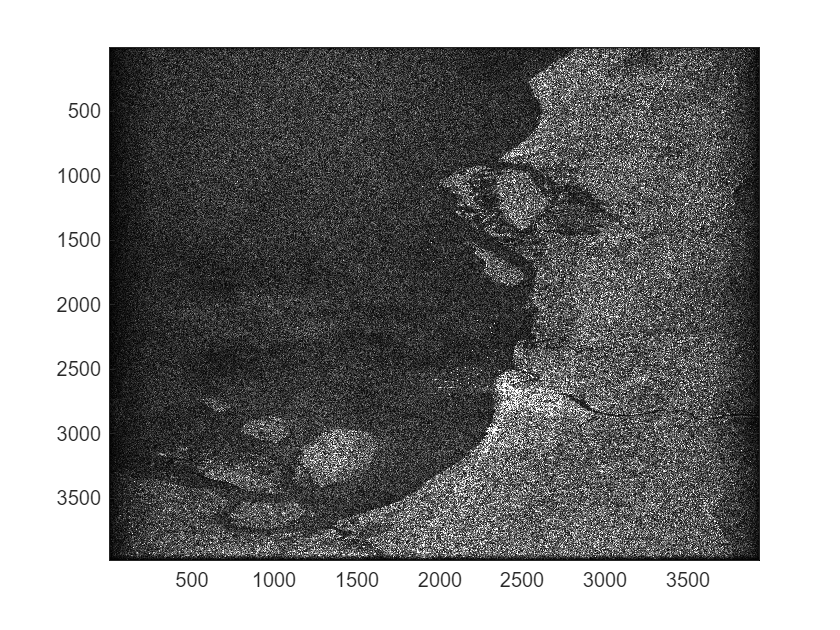


figure
plot_sar(I,99); 

I = abs(I);
th = prctile(I(:),98);
imwrite(imresize(min(I,th)/th,[1000 500]),'test2.jpg')
